# Práctica 03 - Modelización de datos experimentales

#### Autor: Reyes Iglesias Bruno Fernando

**Instrucción:** *Los estudiantes usarán Matlab y Python para modelar matemáticamente los siguientes casos presentados. Se enfocarán en comprender el flujo de programación y visualización de resultados.*

**1.** En la ingeniería de abastecimiento de aguas, el tamaño del reservorio depende de la estimación exacta del flujo de agua en el río del cual se toma. Para algunos rios es difícil obtener registros históricos de muchos años atrás de tales datos de flujo. Por el contrario, datos meteorológicos sobre precipitación de muchos años atrás están a menudo disponibles. Por tanto, con frecuencia es útil determinar una relación entre el flujo y precipitación. Esta relación se puede entonces usar para estimar flujos por años pero solo cuando se hicieron dichas mediciones de precipitación.

Para un río que se va a encauzar a un dique, se tienen los siguientes datos:

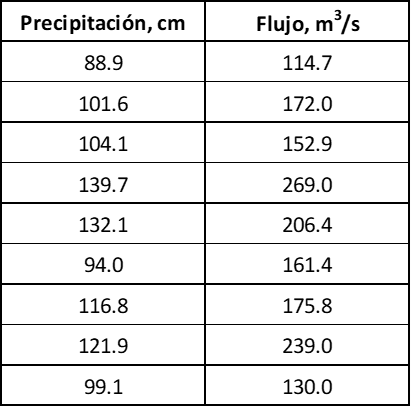

            a. Grafique los datos.

            b. Ajuste a una línea recta. Sobreponga la línea de su gráfica.

            c. Use la mejor línea de ajuste para predecir el flujo de agua anual si la precipitación es de 120 cm.

    **SOLUCIÓN:**

        Primero se debe ingresar los datos, se contruyen 2 vectores que contengan los datos de la tabla, si se desea se puede armar una tabla con el comando `table` para visualizar los datos en la ventana de comandos. Hay otras formas de ingresar datos, como crear una matriz, importar de una hoja de cálculo, entre otros que se pueden revisar en la documentación de MATLAB, pero se tomará lo más sencillo.

%% PROBLEMA 1
% Datos: Precipitación cm (Pre), Flujo m^3/s (Flw)
Pre=[88.9;101.6;104.1;139.7;132.1;94.0;116.8;121.9;99.1];
Flw=[114.7;172.0;152.9;269.0;206.4;161.4;175.8;239.0;130.0];
Tab=table(Pre,Flw,VariableNames={'Precipitacion, cm','Flujo, m^3/s'});
disp(Tab)

    Precipitacion, cm    Flujo, m^3/s
    _________________    ____________

           88.9             114.7    
          101.6               172    
          104.1             152.9    
          139.7               269    
          132.1             206.4    
             94             161.4    
          116.8             175.8    
          121.9               239    
           99.1               130    



        Luego se grafican los datos con el comando `plot` usando un formato para que solo se muestren los puntos.

% a. Graficar los datos
plot(Pre,Flw,'ob')
title('Datos')
xlabel('Precipitacion, cm')
ylabel('Flujo, m^3/s')
grid on
hold on

        Se realiza el ajuste de datos con el comando `fit` en la opción linear (`'poly1'`). También se puede realizar esta tarea de forma interactiva con la aplicación 'Curve Fitter'.

% b. Ajuste a una linea recta. Sobreponga la linea de su grafica
[F,gof]=fit(Pre,Flw,'poly1');
disp(F); disp(gof);

     Linear model Poly1:
     F(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       2.563  (1.462, 3.664)
       p2 =      -104.1  (-227.6, 19.34)
           sse: 3.7582e+03
       rsquare: 0.8123
           dfe: 7
    adjrsquare: 0.7855
          rmse: 23.1708



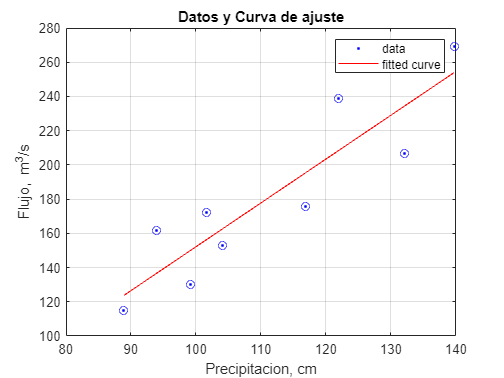

plot(F,Pre,Flw)
title('Datos y Curva de ajuste')
xlabel('Precipitacion, cm')
ylabel('Flujo, m^3/s')
grid on
hold off

        Finalmente se pide predecir el flujo de agua cuando la precipitación es de 120 cm, para lo que se recupera los valores de los parámetros obtenidos de la curva de ajuste con la funcion `coeffvalues` del objeto `cfit` donde se guardaron los datos, en este caso `F`.

% c. Use la mejor linea de ajuste para predecir el flujo de agua anual si la precipitacion es de 120 cm
optimpar=coeffvalues(F);
Flw120=polyval(optimpar,120);
fprintf('El flujo cuando la precipitacion es 120 cm sera: %1.4g m^3/s\n', Flw120)

El flujo cuando la precipitacion es 120 cm sera: 203.4 m^3/s


**2.** La concentración de fósforo total (p en $\textrm{mg}/{\textrm{cm}}^3$) y clorofila (c en $\textrm{mg}/{\textrm{cm}}^3$) para cada uno de los grandes lagos es:

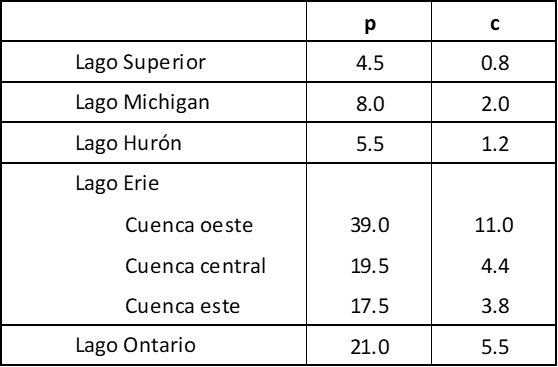

La clorofila c es un parámetro que indica cuanta vida de plantas está suspendida en el agua. Como tal, indica qué tan turbia y opaca aparece el agua. Use los datos anteriores para determinar una relación c como una función de p. Use esta ecuación para predecir el nivel de clorofila que puede esperarse si el tratamiento de desechos es usado para disminuir la concentración de fósforo en la cuenca oeste del Lago Erie a 15 $\textrm{mg}/{\textrm{cm}}^3$.

**    SOLUCIÓN:**

        Igual que el Problema 1, se tiene que la clorofila c es función de p, por lo que se busca una curva de ajuste a los datos obtenidos.

%% Problema 2
% Datos:
p=[4.5;8.0;5.5;39.0;19.5;17.5;21.0];
c=[0.8;2.0;1.2;11.0;4.4;3.8;5.5];
Tab=table(p,c,VariableNames={'Fosforo (p)','Clorofila (c)'});
disp(Tab)

    Fosforo (p)    Clorofila (c)
    ___________    _____________

        4.5             0.8     
          8               2     
        5.5             1.2     
         39              11     
       19.5             4.4     
       17.5             3.8     
         21             5.5     



% Encontrar una curva de ajuste y graficar los datos
[F,gof]=fit(p,c,'poly1');
disp(F); disp(gof);

     Linear model Poly1:
     F(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.2879  (0.2477, 0.328)
       p2 =      -0.629  (-1.427, 0.1685)
           sse: 1.0653
       rsquare: 0.9855
           dfe: 5
    adjrsquare: 0.9826
          rmse: 0.4616



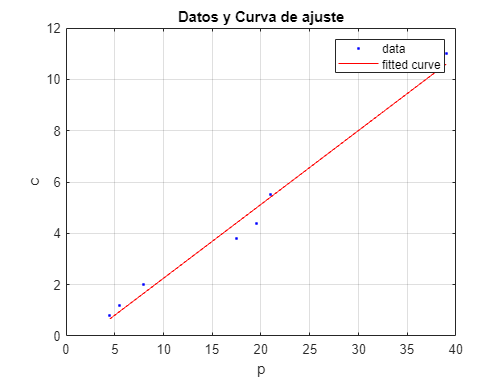

plot(F,p,c)
title('Datos y Curva de ajuste')
xlabel('p')
ylabel('c')
grid on

% Predecir lel nivel de clorofila cuando p = 15 mg/cm^3
optimpar=coeffvalues(F);
c15=polyval(optimpar,15);
fprintf('El nivel de clorofila cuando p = 15 mg/cm^3 es: %1.4g\n', c15)

El nivel de clorofila cuando p = 15 mg/cm^3 es: 3.689


**3. **Tres organismos portadores de enfermedades decaen de manera exponencial en las aguas de un lago de acuerdo con el siguiente modelo:


$$p\left(t\right)=Ae^{-1\ldotp 5t} +Be^{-0\ldotp 3t} +Ce^{-0\ldotp 05t}$$


Calcule la población inicial de cada organismo (A, B y C) dadas las siguientes mediciones:

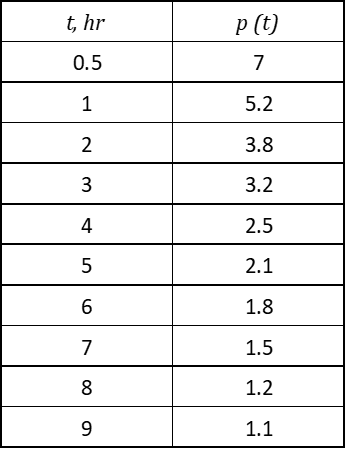

**    SOLUCIÓN:**

        Igual que los problemas anteriores se busca un ajuste de curva que satisfaga el modelo descrito, se por lo que primero se realiza el modelo con el comando `fittype` indicando la variable dependiente `'p'`, independiente `'t'` y las constantes `'A','B','C'`.

%% Problema 3
% Datos:
t=[0.5;1;2;3;4;5;6;7;8;9];
P=[7;5.2;3.8;3.2;2.5;2.1;1.8;1.5;1.2;1.1];
Tab=table(t,P,VariableNames={'Tiempo (hrs)','Poblacion'});
disp(Tab)

    Tiempo (hrs)    Poblacion
    ____________    _________

        0.5              7   
          1            5.2   
          2            3.8   
          3            3.2   
          4            2.5   
          5            2.1   
          6            1.8   
          7            1.5   
          8            1.2   
          9            1.1   



% Encontrar una curva de ajuste de acuerdo al modelo dado y graficar los datos
model=fittype('A.*exp(-1.5.*t)+B.*exp(-0.3.*t)+C.*exp(-0.05.*t)','dependent','P','independent','t','coefficients',{'A','B','C'});
[F,gof]=fit(t,P,model,'StartPoint',[1,1,1]); % StartPoint para indicar un valor incial de calculo (no es necesario)
disp(F); disp(gof);

     General model:
     F(t) = A.*exp(-1.5.*t)+B.*exp(-0.3.*t)+C.*exp(-0.05.*t)
     Coefficients (with 95% confidence bounds):
       A =       3.778  (2.461, 5.095)
       B =       4.387  (3.541, 5.233)
       C =       1.378  (1.068, 1.687)
           sse: 0.1149
       rsquare: 0.9965
           dfe: 7
    adjrsquare: 0.9955
          rmse: 0.1281



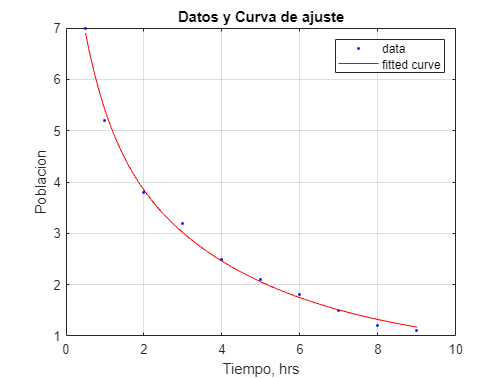

plot(F,t,P)
title('Datos y Curva de ajuste')
xlabel('Tiempo, hrs')
ylabel('Poblacion')
grid on

% Poblacion incial A,B,C
optimpar=coeffvalues(F);
A=optimpar(1);
B=optimpar(2);
C=optimpar(3);
fprintf('La poblacion incial de A es: %1.5g\n', A)

La poblacion incial de A es: 3.7778


fprintf('La poblacion incial de B es: %1.5g\n', B)

La poblacion incial de B es: 4.3872


fprintf('La poblacion incial de C es: %1.5g\n', C)

La poblacion incial de C es: 1.3775
